# Aula 5 - Lugar Das Raízes 


$$G(s)=\frac{K}{s(s+2)(s^2+4s+5)}$$


1º) Verificar os polos e zeros

clear
den=conv(conv([1,0],[1,2]),[1,4,5]);
num=1;
p=roots(den) %polos

p =    0.0000 + 0.0000i
  -2.0000 + 1.0000i
  -2.0000 - 1.0000i
  -2.0000 + 0.0000i


z=roots(num) %zeros


z =

  0×1 empty double column vector



2º) Verificar tipo e ordem

n=length(p) 

n = 4

m=length(z)

m = 0

tipo=sum(p==0)

tipo = 1

3º) Calcular as assíntotas

k=n-m

k = 4

for a=0:(k-1)
    assintotas(a+1)=(180+a*360)/k;
end
assintotas

assintotas =     45   135   225   315


4º) Ponto das assíntotas

sigma=(sum(p)-sum(z))/k

sigma = -1.5000

5º) Pontos de decolagem/pouso

eq característica:


$$K=-\frac{\prod(s-p_i)}{\prod(s-z_i)}$$
 

pontos de decolagem/pouso

 
$$\frac{dK}{ds}=0$$


syms K s
den_s=0;
for a=1:(n+1)
    den_s=den_s+den(a)*s^(n-a+1);
end
den_s %fazer o mesmo pra num_s se tiver zeros

$$den\_s = s^{4}+6\,s^{3}+13\,s^{2}+10\,s$$

eqn=K/den_s+1

$$eqn = \frac{K}{s^{4}+6\,s^{3}+13\,s^{2}+10\,s}+1$$

K=solve(eqn,K)

$$K = -s^{4}-6\,s^{3}-13\,s^{2}-10\,s$$

dkds=diff(K,s)

$$dkds = -4\,s^{3}-18\,s^{2}-26\,s-10$$

pol=fliplr(coeffs(dkds))

$$pol = \left(\begin{array}{cccc} -4 & -18 & -26 & -10 \end{array}\right)$$

pontos=vpa(roots(pol),5)

$$pontos = \left(\begin{array}{c} -0.60184\\ -1.9491+0.59584\,\mathrm{i}\\ -1.9491-0.59584\,\mathrm{i} \end{array}\right)$$

6º) Angulo de saída dos polos complexos

hold off
close all
pzmap(tf(num,den))
grid on

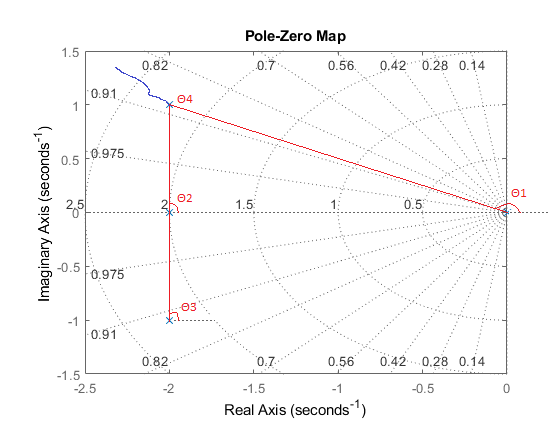

theta4=180-sum(rad2deg(angle(p(2)-p)))+360

theta4 = 206.5651

7º) Ponto de cruze com o eixo imaginário

syms w
eqn3=subs(K,w*1i)

$$eqn3 = -w^{4}+6\,w^{3}\,\mathrm{i}+13\,w^{2}-10\,w\,\mathrm{i}$$


imgcoefs = fliplr(imag(coeffs(eqn3)));
realcoefs = fliplr(real(coeffs(eqn3)));
raizes_w = vpa(roots(imgcoefs),5)

$$raizes\_w = \left(\begin{array}{c} -1.291\\ 1.291 \end{array}\right)$$

w_1 = raizes_w(2);
k_1=0;
for a=1:n
    k_1=k_1+realcoefs(a)*(w_1)^(n-a+1);
end
k_1

$$k\_1 = 18.888888888888084575855324121374$$

7º) Plotar o LR

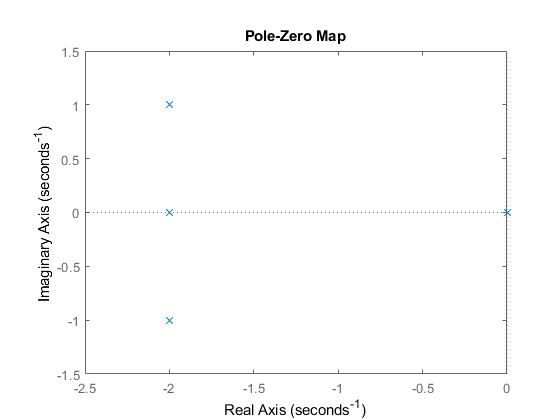

close all
pzmap(tf(num,den))

Após plotar os polos e zeros, lembrar que:

1) Número de ramos = número do polos em malha fechada.

2) LR começa nos polos e termina nos zeros ou no infinito(assíntotas).

3) LR é simétrico em relação ao eixo real.

4) Sobre o eixo real é LR nos pontos em que (p+z) é impar, sendo p e z os números de polos e zeros.

5) Se quiser saber K em um ponto específico é só usar a condição de módulo.

6) LR é sempre função de um K multiplicando. Se o parâmetro que deseja não está multiplicando, deve-se usar a eq característica, isolar esse parâmetro e encontrar uma nova GH para fazer o LR.